# 第五章计算物理作业1，2，3，5，10 （选做13，14）

## 1.研究质点在平方反比引力场中的运动，例如行星绕太阳的运动。设质量为的质点位于力心且固定不动，质量为m的质点在$m_0$产生的引力场中运动，当m与$m_0$相距r时，质点所受万有引力$F=Gm_0m/r^2$，G为引力常量。

### (1) 当质点总能量大于、等于和小于零时，画出质点在平方反比引力场中的运动轨迹。

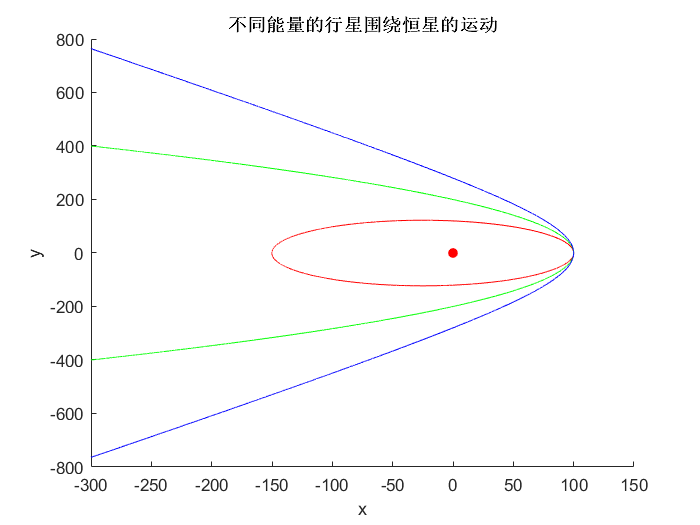

clear;clc;
T=150;
r0=100;     %初始半径r0
theta0=0;   %初始theta角度
k=5000;       %k=G*M
E=[-20 0 20];   %行星不同的能量
v0=sqrt(2.*E+2*k/r0);  %行星的初速度
%行星运动轨迹方程
F=@(t,u)[u(2);u(1).*u(4).^2-k.*u(1).^-2;u(4);-2.*u(2).*u(4)./u(1)];
%星星轨迹作图前准备
figure
xlabel('x');ylabel('y');
axis([-300 150 -800 800]);
title('不同能量的行星围绕恒星的运动');
sun=line(0,0,'color','r','marker','.','markersize',20);
hold on
%能量E小于0的行星
[t,y]=ode45(F,0:0.01:T,[r0 0 0 v0(1)/r0]);
[X,Y]=pol2cart(y(:,3),y(:,1));
h1=plot(X,Y);
set(h1,'color','r')
%能量E等于0的行星
[t,y]=ode45(F,0:0.01:T,[r0 0 0 v0(2)/r0]);
[X,Y]=pol2cart(y(:,3),y(:,1));
X=[X,X];Y=[Y,-Y];
h2=plot(X,Y);
set(h2,'color','g')
%能量E大于0的行星
[t,y]=ode45(F,0:0.01:T,[r0 0 0 v0(3)/r0]);
[X,Y]=pol2cart(y(:,3),y(:,1));
X=[X,X];Y=[Y,-Y];
h3=plot(X,Y);
set(h3,'color','b');

### (2) 当质点总能鼠小于零且保持不变时，改变角动量的大小，画出质点相应的运动轨迹。

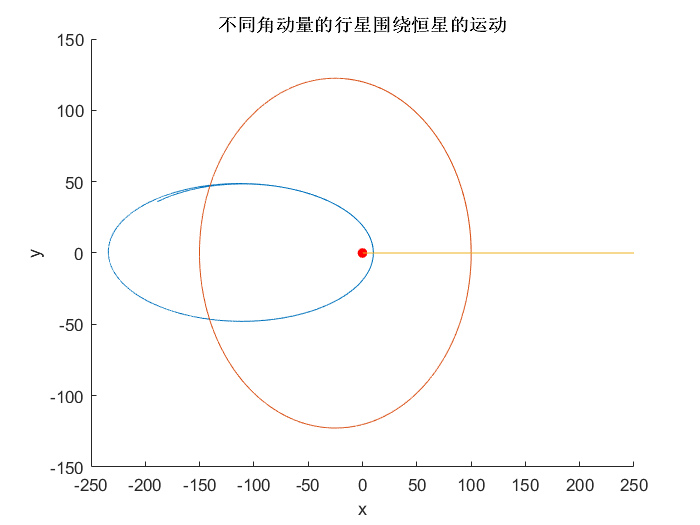

clear;clc;
T=150;
r0=[10 100 250];     %初始半径r0
theta0=0;   %初始theta角度
k=5000;       %k=G*M
E=-20;   %行星不同的能量
v0=sqrt(2*E+2*k./r0);  %行星的初速度
%行星运动轨迹方程
F=@(t,u)[u(2);u(1).*u(4).^2-k.*u(1).^-2;u(4);-2.*u(2).*u(4)./u(1)];
%星星轨迹作图前准备
figure
xlabel('x');ylabel('y');
%axis([-300 150 -800 800]);
title('不同角动量的行星围绕恒星的运动');
sun=line(0,0,'color','r','marker','.','markersize',20);
hold on
for i=1:length(r0)
    [t,y]=ode45(F,0:0.01:T,[r0(i) 0 0 v0(i)/r0(i)]);
    [X,Y]=pol2cart(y(:,3),y(:,1));
    plot(X,Y);
end

## 2.研究平方反比斥力场中粒子的运动。以$\alpha$粒子在重核场中的运动为例，设重核位于力心且固定不动， $\alpha$粒子的质量为m ，它到重核的距离为r ，所受到库仑斥力为$F=k/r^2$，k为由库仑定律确定的常量。画出$\alpha$粒子在不同初始条件下的轨道，通过改变初始条件研究影响散射角的因素。

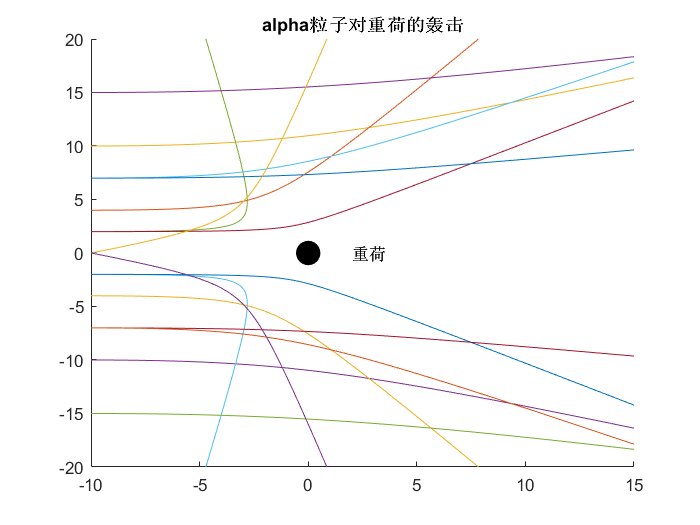

clear;clc;
k=3;
%入射粒子初始位置
y0=[-10,1,10,0;
    -10,1,-10,0;
    -10,1,2,0;
    -10,1,-2,0;
    -10,2,2,0;
    -10,2,-2,0;
    -10,1,4,0;
    -10,1,-4,0;
    -10,1,15,0;
    -10,1,-15,0;
    -10,1,7,0;
    -10,2,-7,0;
    -10,2,7,0;
    -10,1,-7,0;
    -10,1,0,0.4;
    -10,1,0,-0.4;
    ];
%粒子运动方程
F=@(t,y)[y(2);
         k*y(1)/sqrt(y(1).*y(1)+y(3).*y(3)).^3;
         y(4);
         k*y(3)/sqrt(y(1).*y(1)+y(3).*y(3)).^3];
%画靶粒子
line(0,0,'marker','.','markersize',50,'color','k');
text(2,0,'重荷');
axis([-10 15 -20 20])
hold on
%粒子入射
for i=1:length(y0)
    [t,y]=ode45(F,[0:0.1:30],y0(i,:));
    plot(y(:,1),y(:,3));
end
title('alpha粒子对重荷的轰击')

## 3.研究水星近日点的进动。画出水星运动轨道。验证只要质点在有心力场中所受的力与平方反比引力有微小偏离，其轨道就不是闭合椭圆，从而证明广义相对论对万有引力定律的修正将引起椭圆轨道进动。

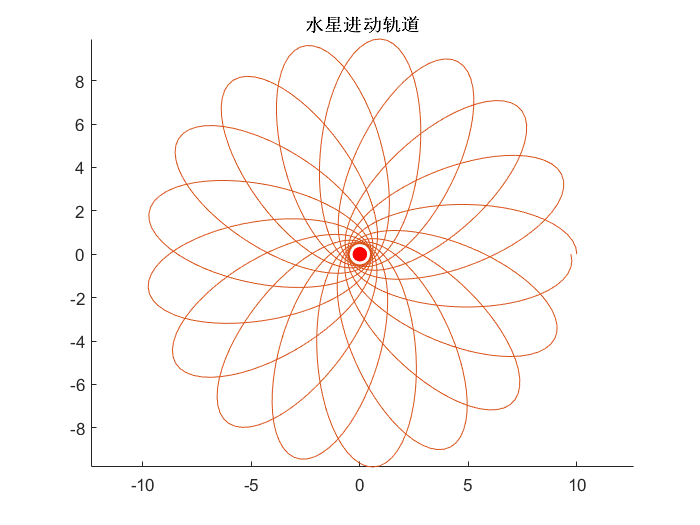

clear;clc;
a=1;b=0.05;
%定义水星进动方程
F=@(theta,u)[u(2);-u(1)+a+b*u(1)^2];
%画太阳
line(0,0,'marker','.','markersize',30,'color','r');
axis equal
hold on
[theta,u]=ode45(F,0:pi/100:36*pi,[0.1 0]);
[X,Y]=pol2cart(theta,1./u(:,1)); %极坐标转换直角坐标
plot(X,Y) %运动轨迹作图
title('水星进动轨道')

## 5.三质点系统的微振动。研究两个弹簧连接三个质点组成的一维振动系统的运动。

### (1) 用三种不同的方法即矩阵方法、快速傅里叶变换法和拉普拉斯变换法分别求出振动系统的简正频率。

#### a.矩阵方法

clear;clc;
m=3; M=4;k=50;
K=[k,-k,0;-k,2*k,-k;0,-k,k];
S=[m,0,0;0,M,0;0,0,m];
[O,L]=eig(K,S);
OL=sqrt(L)

OL =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   4.0825 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   6.4550 + 0.0000i


#### b.快速傅里叶变换方法

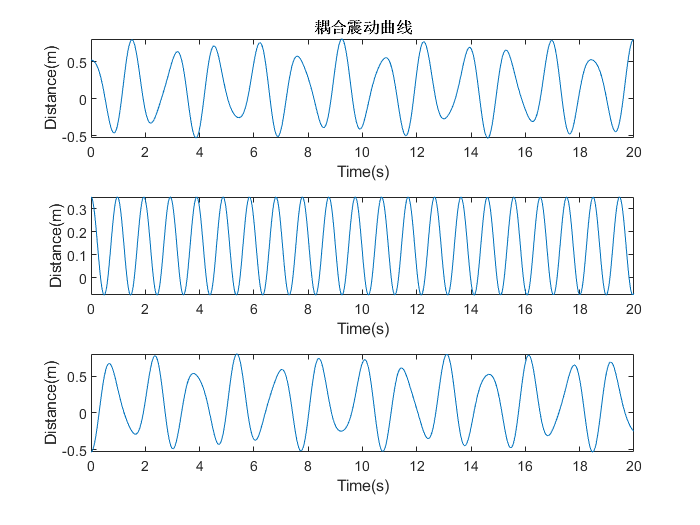

clear;clc;
XS10=0.52;XS20=0.35;XS30=-0.53;     %初始位移
m=3; M=4;k=50;
F=@(t,y)[y(4);
         y(5);
         y(6);
         k/m*(y(2)-y(1));
         k/M*(y(3)-y(2))-k/M*(y(2)-y(1));
         k/m*(y(2)-y(3))];
[t,u]=ode45(F,0:0.01:33,[XS10,XS20,XS30,0,0,0]);
%画三个质点的位移
subplot(3,1,1);
plot(t(1:2000),u(1:2000,1))
title('耦合震动曲线')
xlabel('Time(s)');ylabel('Distance(m)');
subplot(3,1,2);
plot(t(1:2000),u(1:2000,2))
xlabel('Time(s)');ylabel('Distance(m)');
subplot(3,1,3);
plot(t(1:2000),u(1:2000,3))
xlabel('Time(s)');ylabel('Distance(m)');

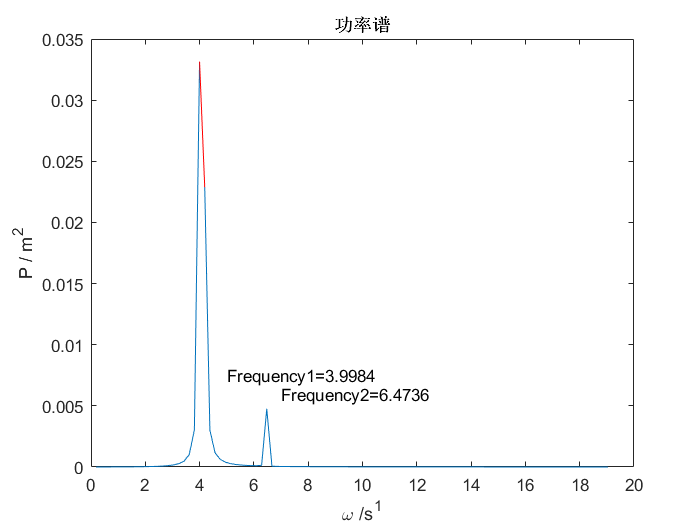

%傅里叶变换求本征频率
Y=fft(u(:,1));
Y(1)=[];
n=length(Y)/2;
power=abs(Y(1:n)).^2/(length(Y).^2);
freq=100*(1:n)/length(Y);
power1=power;
[id1,daa1]=max(power1);
power1(daa1)=0;
[id2,daa2]=max(power1);
WF=2*pi*[freq(daa1),freq(daa2)];

figure
plot(2*pi*freq(1:100),power(1:100))
hold on
title('功率谱')
xlabel('\omega /s^{1}');ylabel('P / m^2')
plot(WF,[power(daa1),power(daa2)],'r','markersize',40)
text(5,7.5e-3,'Frequency1=3.9984')
text(7,6e-3,'Frequency2=6.4736')

#### c.拉普拉斯

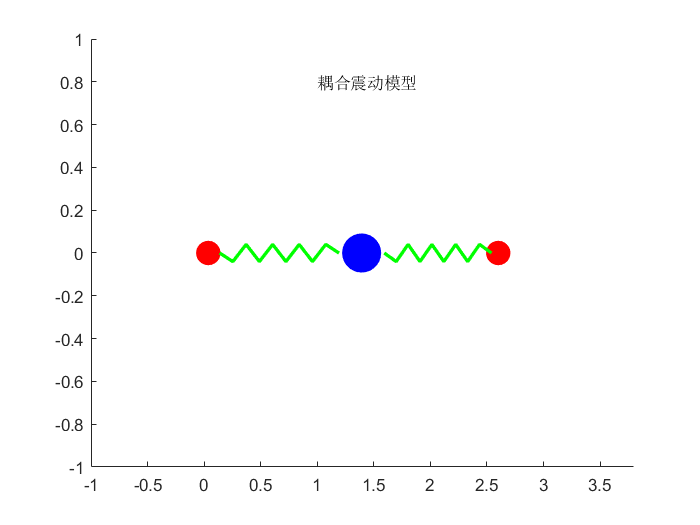

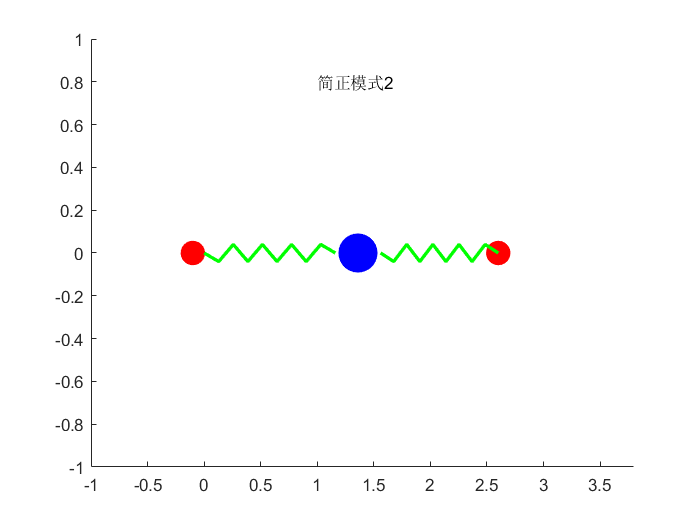

clear;clc;
syms k M m w XL10 real;

syms XL1(t);            %表示位移XL1
dXL1=diff(XL1,t,1);     %表示XL1的一阶导数
ddXL1=diff(XL1,t,2);    %表示XL1的二阶导数

syms XL2(t);            %表示位移XL2
dXL2=diff(XL2,t,1);     %表示XL2的一阶导数
ddXL2=diff(XL2,t,2);    %表示XL2的二阶导数

syms XL3(t);            %表示位移XL3
dXL3=diff(XL3,t,1);     %表示XL3的一阶导数
ddXL3=diff(XL3,t,2);    %表示XL3的二阶导数

%表示方程
eq1=m*ddXL1-k*(XL2-XL1);           
eq2=M*ddXL2+k*(XL2-XL1)-k*(XL3-XL2);
eq3=m*ddXL3+k*(XL3-XL2);
syms s;
%对方程进行拉普拉斯变换
L1=laplace(eq1,t,s);    
L2=laplace(eq2,t,s);    
L3=laplace(eq3,t,s);

%替换初值
NXL1=subs(L1,{XL1(0),XL2(0),XL3(0),dXL1(0),dXL2(0),...
     dXL3(0)},{XL10,0,0,0,0,0});
NXL2=subs(L2,{XL1(0),XL2(0),XL3(0),dXL1(0)',dXL2(0),...
     dXL3(0)},{XL10,0,0,0,0,0});   
NXL3=subs(L3,{XL1(0),XL2(0),XL3(0),dXL1(0),dXL2(0)',...
     dXL3(0)},{XL10,0,0,0,0,0});

%合并同类项
syms LXL1 LXL2 LXL3
NNXL1=subs(NXL1,{laplace(XL1(t),t,s),laplace(XL2(t),t,s),...
      laplace(XL3(t),t,s)},{LXL1,LXL2,LXL3});  %替换拉氏符号
CXL1=collect(NNXL1,LXL1);
NNXL2=subs(NXL2,{laplace(XL1(t),t,s),laplace(XL2(t),t,s),...
      laplace(XL3(t),t,s)},{LXL1,LXL2,LXL3});  %替换拉氏符号
CXL2=collect(NNXL2,LXL2);
NNXL3=subs(NXL3,{laplace(XL1(t),t,s),laplace(XL2(t),t,s),...
      laplace(XL3(t),t,s)},{LXL1,LXL2,LXL3});  %替换拉氏符号
CXL3=collect(NNXL3,LXL3);
%逆变换求位移XL1
[j1,j2,j3]=solve(CXL1,CXL2,CXL3,LXL1,LXL2,LXL3); %解变形后方程
XL1=ilaplace(j1,s,t);
XL2=ilaplace(j2,s,t);
XL3=ilaplace(j3,s,t);
%求数值结果
XL1=eval(subs(XL1,{m,M,k,XL10},{3,4,50,0.2}));
XL2=eval(subs(XL2,{m,M,k,XL10},{3,4,50,0.2}));
XL3=eval(subs(XL3,{m,M,k,XL10},{3,4,50,0.2}));
%解数值化
XL1=vpa(XL1,4);
XL2=vpa(XL2,4);
XL3=vpa(XL3,4);

XL1=matlabFunction(XL1);
XL2=matlabFunction(XL2);
XL3=matlabFunction(XL3);

L=1;
a=0.2;
t=0:0.01:33;

sp{1}='耦合震动模型';
sp{2}='简正模式1';
sp{3}='简正模式2';

figure
axis([-1,2*L+4*a+1,-1,1]);
hold on

for n=1:3
	cla
    text(1,0.8,sp{n})
    if n==1
    elseif n==2
        XL1=.4e-1*cos(6.456*t);
        XL2=-.6e-1*cos(6.456*t);
        XL3=.4e-1*cos(6.456*t);
    elseif n==3
        XL1=.1*cos(4.082*t);
        XL2=.6e-1*ones(1,1000);
        XL3=-.1*cos(4.082*t);
	end

	qiou1=line(0, 0,'color','r','marker','.','markersize', 50,'erasemode','xor');%画球
    qiou2=line(L+3*a/2,0,'color','b','marker','.','markersize', 80,'erasemode','xor');
    qiou3=line(2*L+3*a,0,'color','r','marker','.','markersize',50,'erasemode','xor');
    xx1=linspace(a/2,L+a/2,10); %改以下画弹簧
    xx2=linspace(L+5*a/2,2*L+5*a/2,10);
    yy1=[0,-0.04,0.04,-0.04,0.04,-0.04,0.04,-0.04,0.04,0];
    yy2=yy1;
    tanhuang1=line(xx1,yy1,'color','g','linestyle','-','erasemode','xor','linewidth',2);
    tanhuang2=line(xx2,yy2,'color','g','linestyle','-','erasemode','xor','linewidth',2);
    pause(0.2)
    for i=1:1000 %动画
        xx1=linspace(XL1(i)+a/2,L+a/2+XL2(i),10);
    	xx2=linspace(XL2(i) +L+5*a/2,2*L+5*a/2+XL3(i),10);
        set(tanhuang1,'XData',xx1,'YData',yy1);
        set(tanhuang2,'XData',xx2,'YData',yy2);
        set(qiou1,'XData', XL1(i),'YData',0);
        set(qiou2,'XData',L+3*a/2+XL2(i),'YData',0);
        drawnow;
    end
end

## 10.常微分方程：$\dot{y}=-1000(y-sint)+cost, y(0)=1$在区间$0\leq t \leq1$上略为刚性的。

### （1）求出方程精确解。

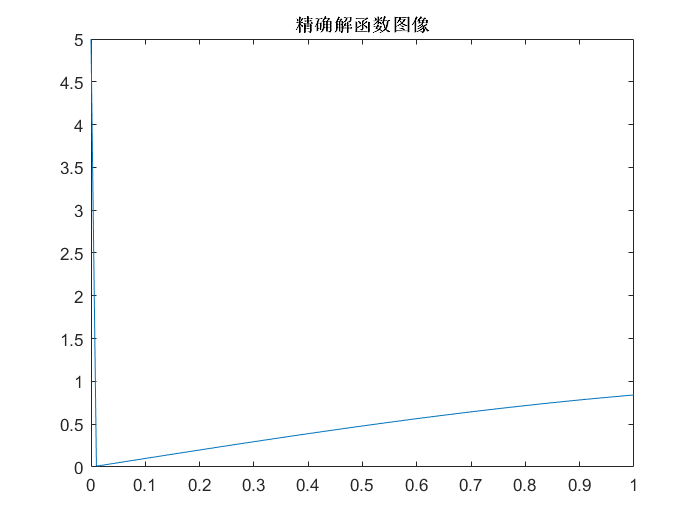

clear;clc;
%利用dsolve求解
syms y(t);
equ=diff(y,t)==-1000*(y-sin(t))+cos(t);
cond=y(0)==5;
u(t)=dsolve(equ,cond);
m=0:0.01:1;
figure(1)
plot(m,u(m));
title('精确解函数图像')

### （2）将两种解绘在同一幅图上，分别用“x”和"o"来表示他们。

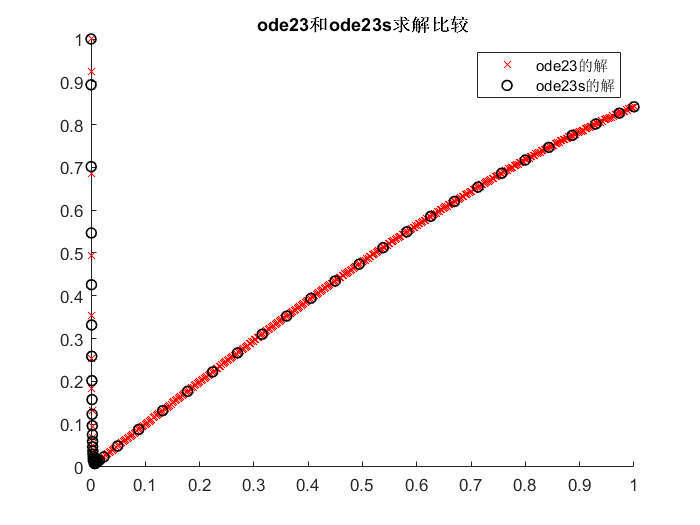

F=@(t,u)[-1000*(u-sin(t))+cos(t)];
[t,y]=ode23(F,[0 1],1);
[ts,ys]=ode23s(F,[0 1],1);
figure(2)
hold on
plot(t,y,'rx','LineWidth',0.5)
plot(ts,ys,'ko','LineWidth',1)
title('ode23和ode23s求解比较')
legend({'ode23的解','ode23s的解'})

### （3）将图像放大，仔细观察图像上变化剧烈的地方，比较这两种方法的步长大小。

在图像剧烈变化的地方ode23和ode23s的步长大致一致。

### （4）再观察图像变化缓慢的地方，再比较两种方法的步长，哪种方法的步长更大，也即是哪种方法的计算效率更高？

在图像变化缓慢的地方ode23远远大于ode23s的步长。